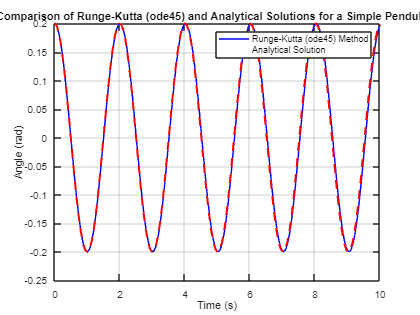

% Constants
g = 9.81;  % acceleration due to gravity (m/s^2)
length = 1; % length of the pendulum (m)
total_time = 10;  % total simulation time (s)

% Initial conditions
theta0 = 0.2; % initial angle (rad)
omega0 = 0.0;  % initial angular velocity (rad/s)

% Define the ODE function for ode45
odefun = @(t, y) [y(2); -g/length * sin(y(1))];

% Time span for the simulation
tspan = [0 total_time];

% Solve the ODE using ode45
[t, y] = ode45(odefun, tspan, [theta0; omega0]);

% Extract theta and omega from the solution
theta_values = y(:, 1);

% Time values for the analytical solution
time_values_analytical = t; % to ensure we compare at the same points

% The analytical solution
% Natural frequency of the pendulum
omega_natural = sqrt(g / length); 

% Analytical solution for theta as a function of time
theta_analytical = theta0 * cos(omega_natural * time_values_analytical);

% Plotting
figure;
% Plot the Runge-Kutta (ode45) Method
plot(t, theta_values, 'b-', 'DisplayName', 'Runge-Kutta (ode45) Method');
hold on;
% Plot the Analytical Solution
plot(time_values_analytical, theta_analytical, 'r--','LineWidth',2, 'DisplayName', 'Analytical Solution');
xlabel('Time (s)');
ylabel('Angle (rad)');
title('Comparison of Runge-Kutta (ode45) and Analytical Solutions for a Simple Pendulum');
legend show;
grid on;